t = 0:0.01:30;
y = exp(-0.12*t).*sin(5*t) + 0.3*cos(2*t);
u = exp(-0.12*t) + 0.3;
l = -exp(-0.12*t) - 0.3;
plot(t, y);
hold on
plot(t, u, 'r--');
plot(t, l, 'r--');

idx = find(y(2:end-1) > y(1:end-2) & y(2:end-1) > y(3:end)) + 1;

plot(t(idx), y(idx), 'ko');

result_table = table(t(idx)', y(idx)', 'VariableNames', {'t_value', 'f_t_value'});
disp(result_table);

    t_value    f_t_value
    _______    _________

       0.3       1.2098 
      1.57      0.52828 
      2.84      0.95686 
      4.04       0.5337 
      5.38      0.44424 
      6.56      0.70239 
      7.85      0.08978 
      9.14      0.58298 
     10.28       0.2222 
     11.72      0.18078 
     12.82      0.46719 
     14.13      -0.1166 
     15.46      0.41179 
     16.44      0.10089 
     19.06      0.36202 
     20.41     -0.21369 
      21.8      0.33804 
     25.28      0.31941 
     28.15      0.31064 



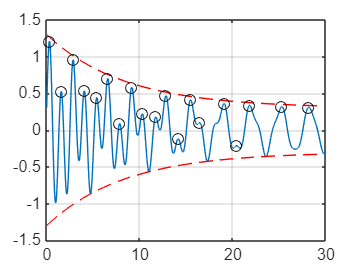


grid on;

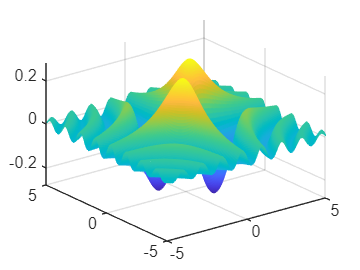

clc; clear;
x = -5 : 0.05 : 5;
y = -5 : 0.05 : 5;

[x,y] =meshgrid(x,y);
z = sin(x.*y)./(1+ x.^2 + y.^2);

figure;
mesh(x,y,z);

figure;
contour(x,y,z,25);

abs_z = abs(z);
[max_val, idx] = max(abs_z, [], 'all');
disp(max_val);

    0.2805




[row, col] = ind2sub(size(z), idx);

max_x = x(row, col);
max_y = y(row, col);

fprintf('최댓값 위치 - x좌표: %f, y좌표: %f\n', max_x, max_y);

최댓값 위치 - x좌표: -1.000000, y좌표: -1.000000


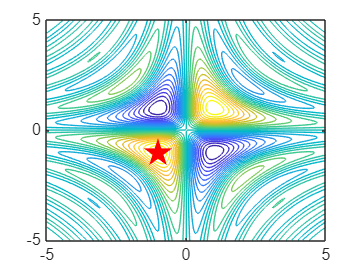


hold on;
plot(max_x, max_y, 'rp', 'MarkerSize', 15, 'MarkerFaceColor', 'r');

A = [7 2 1; 2 6 -2; 1 -2 5];
[V, D] = eig(A)

V =     0.4219    0.5548    0.7171
   -0.6189   -0.4018    0.6749
   -0.6626    0.7285   -0.1738


D =     2.4953         0         0
         0    6.8646         0
         0         0    8.6400


val = diag(D)

val =     2.4953
    6.8646
    8.6400


[v_max, idx] = max(val)

v_max = 8.6400

idx = 3

v = V(:, idx)

v =     0.7171
    0.6749
   -0.1738


v_unit = v/norm(v)

v_unit =     0.7171
    0.6749
   -0.1738


verification = A * v_unit - v_max * v_unit;

fprintf('가장 큰 고유값 (v_max): %f\n', v_max);

가장 큰 고유값 (v_max): 8.640023


disp('해당 고유벡터 v:');

해당 고유벡터 v:


disp(v_unit);

    0.7171
    0.6749
   -0.1738



disp('검증 결과');

검증 결과


disp(verification);

   1.0e-14 *

   -0.0888
    0.3553
    0.0444



clc; clear;
X = [2 5 1; 4 8 3; 6 11 7; 9 15 10; 13 20 14];
mean(X)

ans =     6.8000   11.8000    7.0000


X_c = X - mean(X)

X_c =    -4.8000   -6.8000   -6.0000
   -2.8000   -3.8000   -4.0000
   -0.8000   -0.8000         0
    2.2000    3.2000    3.0000
    6.2000    8.2000    7.0000


S = X_c'*X_c

S =    74.8000  101.8000   90.0000
  101.8000  138.8000  123.0000
   90.0000  123.0000  110.0000


[V, D] = eig(S)

V =     0.7058    0.5204    0.4806
   -0.6833    0.3214    0.6556
    0.1867   -0.7911    0.5824


D =     0.0473         0         0
         0    0.8388         0
         0         0  322.7139


e_values = diag(D);
[max_val, idx] = max(e_values);
max_vec = V(:, idx)

max_vec =     0.4806
    0.6556
    0.5824


A = [5 2 -1; -2 6 3; 1 -1 7];
b = [8;5;12];

x1 = inv(A)*b

x1 =     1.6692
    0.6084
    1.5627


x2 = A\b

x2 =     1.6692
    0.6084
    1.5627


x1-x2

ans = 1.0e-15 *

    0.2220
    0.2220
         0


det(A)

ans = 263

det(A) 가 263 이므로 해가 유일하게 존재한다

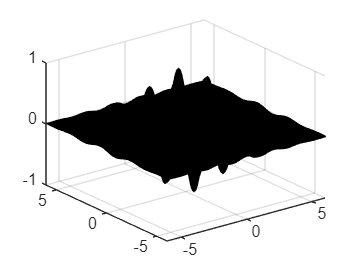

clc; clear;
x = -6 : 0.05 : 6;
y = -6 : 0.05 : 6;

[X, Y] = meshgrid(x,y);
Z = exp(-0.08*(X.^2+Y.^2)).*cos(3*X).*sin(2*Y);

figure;
surf(X,Y,Z);

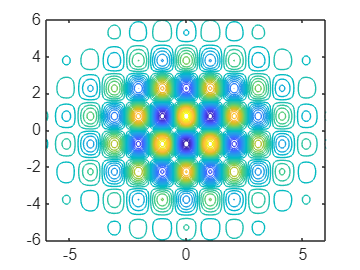

figure;
contour(X,Y,Z,30);

[max_val, max_idx] = max(Z(:))

max_val = 0.9536

max_idx = 29056

[min_val, min_idx] = min(Z(:))

min_val = -0.9536

min_idx = 29026


[max_row, max_col] = ind2sub(size(Z), max_idx);
[min_row, min_col] = ind2sub(size(Z), min_idx);

max_x = X(max_row, max_col)

max_x = 0

max_y = Y(max_row, max_col)

max_y = 0.7500

min_x = X(min_row, min_col)

min_x = 0

min_y = Y(min_row, min_col)

min_y = -0.7500

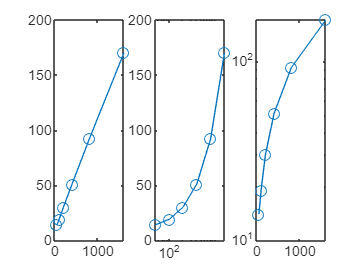

n = [50 100 200 400 800 1600];
T = [14 19 30 51 92 170];

subplot(1,3,1);
plot(n,T,'o-');
subplot(1,3,2);
semilogx(n,T,'o-');
subplot(1,3,3);
semilogy(n,T,'o-');

plot(n,T,'o-')

t = 0 : 0.01 : 24;
P = 50 + 18*sin((pi*t)/12)+6*cos((pi*t)/4);

figure;
plot(t, P);
grid on;
hold on;
[max_val, max_idx] = max(P);
disp(max_val);

   72.1731



max_t = t(max_idx)

max_t = 7.5000

[min_val, min_idx] = min(P);
disp(min_val);

   27.8269



min_t = t(min_idx)

min_t = 19.5000

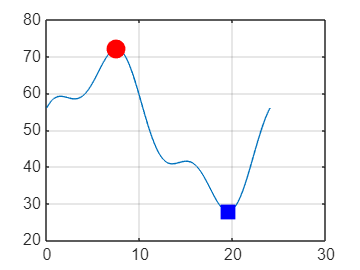

plot(max_t, max_val, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); 
plot(min_t, min_val, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'b');

clc; clear;
X = [1 3 0;2 5 1; 4 8 3; 7 12 5;11 17 9];
x1 = X(:,1);
x2 = X(:,2);
x3 = X(:,3);

get_theta = @(a, b) acosd(dot(a, b) / (norm(a) * norm(b)));
theta12 = get_theta(x1, x2);
theta13 = get_theta(x1, x3);
theta23 = get_theta(x2, x3);

theta = [theta12, theta13, theta23]

theta =     7.1357    6.1221   12.8186



[min_angle, idx] = min(theta);
min_angle

min_angle = 6.1221


if idx == 1
    fprintf('가장 방향이 비슷한 센서: 1번과 2번\n');
elseif idx == 2
    fprintf('가장 방향이 비슷한 센서: 1번과 3번\n');
else
    fprintf('가장 방향이 비슷한 센서: 2번과 3번\n');
end

가장 방향이 비슷한 센서: 1번과 3번


clc; clear;
A = [9 -2 -1; -2 8 -3; -1 -3 10];
b = [15;7;11];
I = A\b

I =     2.3834
    2.2228
    2.0052



disp('가역행렬');

가역행렬


if det(A)~=0
    fprintf('YES');
else
    fprintf('NO');
end

YES


abs(I)

ans =     2.3834
    2.2228
    2.0052


[max_I, idx] = max(abs(I))

max_I = 2.3834

idx = 1

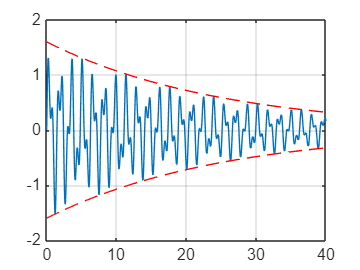

t = 0 : 0.01 : 40;
y = exp(-0.04*t).*(sin(4*t)+0.6.*sin(9*t));
figure;
plot(t, y);
grid on;
hold on;

u = 1.6*exp(-0.04*t);
l = -1.6*exp(-0.04*t);
plot(t, u, 'r--');
plot(t, l, 'r--');

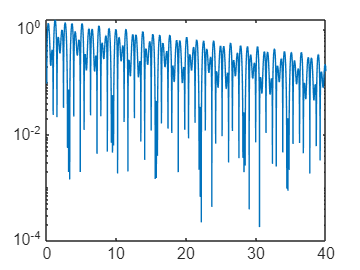


figure;
semilogy(t,abs(y));


u_0 = u(1)

u_0 = 1.6000

u_40 = u(end)

u_40 = 0.3230

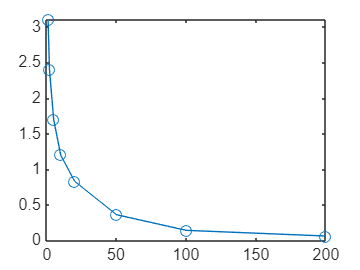

epoch = [1, 2, 5, 10, 20, 50, 100, 200];
loss =  [3.1, 2.4, 1.7, 1.2, 0.83, 0.36, 0.14, 0.06];

figure;
plot(epoch,loss,'o-');

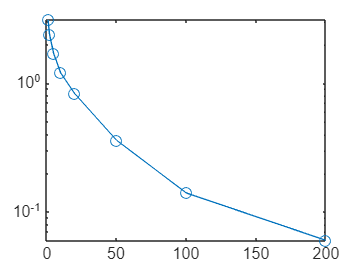

figure;
semilogy(epoch,loss,'o-');


r = loss(2:end)./loss(1:end-1);
mean(r)

ans = 0.5902

평균이 0.5902 로 1보다 작아서 loss 는 전박적으로 감소한다고 할수있다.